There are currently 3 defined kernel types:

EQ - exponential Quadratic (SE squared exponential)

RQ - Rational Quadratic (alpha=1)

Matern52

These kernels can be added subtracted multiplied and divided

The GP class takes a mean function and a kernel.

it then can be conditioned on data x and y and can then be trained using mean aposteriori HP selection.

f1 = @(x) (6*x(:,1)-2).^2.*sin(12*x(:,2)-4);%.*sin(24*x-1);

xx = lhsdesign(100,2);
yy = f1(xx);

x1 = lhsdesign(200,2);
y1 = f1(x1)+normrnd(0*x1(:,1),0*x1(:,1));

a = means.const(0)

a =   const with properties:

         meanz: {[1×1 means.const]}
        coeffs: {[0]}
    operations: []



d = kernels.EQ(1,0.2);

d.signn = eps;

Z = KISSGP(a,d,100);

tic
Z1 = Z.condition(x1,y1,[0 0],[1 1]);
toc

Elapsed time is 0.738540 seconds.


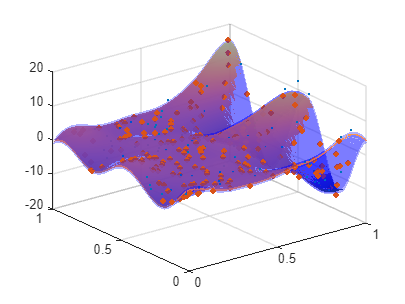

figure
utils.plotSurf(Z1,2,1)
hold on
plot3(xx(:,1),xx(:,2),yy,'.')
plot3(x1(:,1),x1(:,2),y1,'.','MarkerSize',12,'LineWidth',3)

tic
[Z2] = Z1.train();
toc

Elapsed time is 7.606357 seconds.


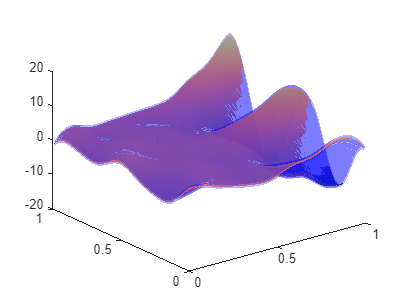

figure
hold on
utils.plotSurf(Z2,2,1)
view(3)

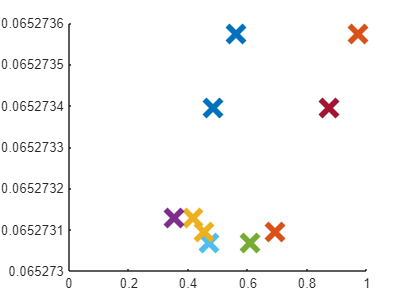

figure
hold on
tic
for i = 1:5
    [x{i},R{i}] = BO.argmax(@BO.maxVAR,Z2);
    plot(x{i},R{i},'x','MarkerSize',18,'LineWidth',4)
end
xlim([0 1])

toc

Elapsed time is 1.752904 seconds.


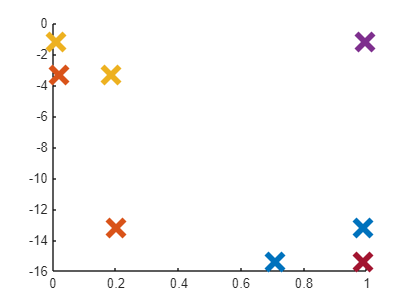

figure
hold on
tic
for i = 1:5
    [x{i},R{i}] = BO.argmin(@BO.LCB,Z2);
    plot(x{i},R{i},'x','MarkerSize',18,'LineWidth',4)
end
xlim([0 1])

toc

Elapsed time is 1.799353 seconds.
